### **NavigationDemo.mlx** runs the system for navigating a rover around the Olin O

This script creates the code using a set of pre-made functions to control the 3 Rover RC servomotors (steering, drive and payload motor) attached to the three pwm ports on a standard SparkFun Servo-pHAT board (you can easily figure out how to attached the pan-tilt servos if you use them), to talk to the Rover's qwiic based SparkFun GPS sensor and to read analog sensors from the two qwiic based SparkFun 12bit ADC boards. The drivers for the Servo pHat are in a file called **I2C_Servo_pHAT.m** which must be in same folder as this code. Please use the **snapshotCustom.m** function with your Pi-Cam, it must also be in the same folder as this code. Please add the **ads1015.m** function to this folder to support your two 12ADC boards. And finally use the **UBX_CLASS_ID.m, UBX.M **and **NEO_M8U.m**  files for your GPS, they all must also be in the same working folder as this code.

* There is a lot of complex device driver code in these supplimentary MATLAB files, please don't open and mess with them, they can't be easily fixed if you break something.*

**Wiring assumptions **(note: if you change your Rover's wiring you must change code to match !):

It is assumed that the three motors are connected to the pHAT through an Actobotics Servo Power isolation board (as shown below), and that the power isolation board is set up to recieve an RC style **pwm** velocity commands from the  Pi Servo pHAT and 7.2 VDC power from the rovers battery through its speed control unit. 

1) Please plug steering motor into pHAT-channel 1 and drive motor amplifier into pHAT-channel 3 as shown. Plug Your payload, pan and tilt servos into any other odd numbered spots.  

2) Please connect your SparkFun GPS-16329 GPS to Qwiic serial bus as shown, be extremly careful with interface cable bewteen SMA and UFL antena cable, you can only plug it into your GPS once or twice. Once plugged in properly, please never remove it. Your GPS is really expensive and this set of hardware is the ONLY ONE, your team gets. No spares.

3) Please add the two SparkFun Qwiic ADC boards to the Qwiic bus as shown and then carefully attached all of your Sharp IR and Maxbotix Sonars to them. You will need to permenantly modify address and pot jumpers on these boards so that internal pot and addresses don't conlict. See Dave B for modification details.   

PUT DIAGRAM HERE

This test code is a scafolding for your Rover control code. This Script will first set up each of the hardware subsystems and create the OCU displays to observe them (code that runs once) and then will move into a continuous loop so that you can experimentally collect data from them for your Rover code (code that runs in control loop). It will aslo let you collect your Rover's current GPS position as well as observe the raw input analog signal voltage from your Rover's Sharp IR Range and Maxbotic Sonar sensors. You will still need to add calibration code to each of those to turn those voltages into useful range measurements. Please note, because of the wierdness of runing interperted code over a WiFi link to the Pi, this loop will run very slowly at about 2 seconds per cycle. Thats normal. Matlab engineers and Dave are working on a path to speed this up.

**Note! Never hook up your Raspberry Pi HOT, Never ever let 7.2V battery voltage touch any Pi GPIO pins!!!!  Please don't burn out your Pi.**

*At end of each programming session, please don't forget to shutdown your Pi cleanly by using the follwing at the command line:*

## `h = Pi`

## `h.execute('sudo shutdown -h now')`

If you don't shut down cleanly before a poweroff, you risk corrupting the Linux build on your Pi and trashing it for future use.

Nabih Estefan, Olivia Jo Bradley, Maya Sivanandan, Chris Allum, Izzie Abilheira, Oscar De La Garza 

April 2021 - Rev A

clc                             %  clear command window
clear all                       % clear MATLAB workspace
close all                       % close existing windows
addpath('functions/');          % add path to folder with functions
addpath('functions/SENSE/');    % add path to folder with functions
addpath('functions/THINK/');    % add path to folder with functions
addpath('functions/ACT/');      % add path to folder with functions
addpath('functions/SETUP/');    % add path to folder with functions
addpath('functions/PROCESSING/');    % add path to folder with functions
% profile on                      % profile used to time each segment of code

**Set up  control system** ( code that runs once )

% create Raspberry PI  and RC servo ref-objects
  disp('note: It takes a 10 seconds or so to download code to Raspberry PI '); 

note: It takes a 10 seconds or so to download code to Raspberry PI 


  [Pi, blinkLED]= SETUP_pi('192.168.16.68');
% Turn on board LED on and off to signal program has started 
  Blink(Pi,blinkLED,10);
  disp('Warning!  Rover Active! '); 

Warning!  Rover Active! 


Check everything is plugged in on i2c Qwiic bus (should see devices at  servo 0x40, GPS 0x42, ADC 0x48 0x49, Pi 0x70 

scanI2CBus(Pi);

First, set up your Rover's Servos

% Configure Servo pHAT driver board (address 0x40), set servos to null position.
roverServos = I2C_Servo_pHAT(Pi);

ACT_moveRover(roverServos,0,0);
ACT_moveCam(roverServos,90,40);
ACT_movePayload(roverServos,0);
  
%   pinSteer = 1;                                   % set Steer servo to pin 1
%   pinSpeed = 2;                                   % set Speed servo to pin 3
%   pinCamTilt = 4;                                 % set PiCam tilt servo to pin 4
%   pinCamPan = 5;                                  % set PiCam pan servo to pin 5
%   pinPayload = 6;                                % set Payload Close servo to pin 6
%  
 % Visualize the test servo commands in  coordinate system.
 % create a new free-standing figure to display the servo data, rover
 % at center
%     localServoPlot=figure('Name','RoverServoSettings (trigger to STOP)','NumberTitle','off','Visible','on');
%     PlotServoSettings(localServoPlot,comSteer,comSpeed)    

Next set up you Pi-Cam

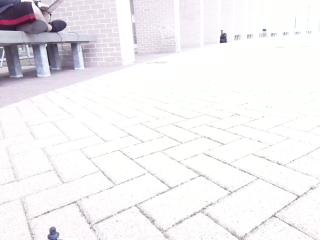

% To create a connection to the V2 Pi Camera
roverCam = cameraboard(Pi,'Resolution','320x240');

% Fix auto exposure problem , set eposure to work in lab lighting
% set whitebalance to manual too. Auto exposure and white balance drive
% computer vison algorythms crazy by constantly changing
SETUP_piCam(roverCam);  

% Acquire a Frame
img = snapshotCustom(roverCam);

% Display the frame in the imaqtool window
% imaqtool launches an interactive GUI to allow you to explore, configure, 
% and acquire data from your installed and supported image acquisition devices.
% imtool(img);                 % can comment this out when you confirm all is working

% explore image with tool
% gCamTest= input('experiment with image tool, type G, then hit ENTER ','s');   % can comment this out when you confirm all is working
% clc;

% livescript does some funky stuff when you try to update in line images quickly, so
% create a free floating figure for images to deal with livescript update problem
piCamWindow = figure('name',' Pi Camera','NumberTitle','off','Visible','on');
figure(piCamWindow)                              % go to camWindow for imshow           
imshow(img,'Border','tight')

% create two SparkFun Qwiic Analog Input adc device that are present on i2c
% bus 1 at address 0x48 and at adress 0x49

[adcDevice1, adcDevice2] = SETUP_adc(Pi);

rawRangeData = SENSE_adc(adcDevice1, adcDevice2);

% Visualize the test sensor scan data in  coordinate system.
% create a new free-standing figure to display the local sensor data, rover
% at center
%     localSensorPlot=figure('Name','LocalSensorMap','NumberTitle','off','Visible','on');
%     PlotSensorData(localSensorPlot, rawRangeData);

Create GPS object and collect first Rover GPS location

see [https://learn.sparkfun.com/tutorials/sparkfun-gps-dead-reckoning-neo-m8u-hookup-guide](https://learn.sparkfun.com/tutorials/sparkfun-gps-dead-reckoning-neo-m8u-hookup-guide) for hookup and technical details

Please see [https://learn.sparkfun.com/tutorials/three-quick-tips-about-using-ufl](https://learn.sparkfun.com/tutorials/three-quick-tips-about-using-ufl) for how to connect your ufl antenna and be 

extraodinarily careful when making the actual connection. Break this connector and GPS is toast and your team doesn't have a spare.

**Note: You will need to connect your GPS over USB to your laptop and run U-Center to configure your GPS before using.** See Canvas for details.

First time you hook up GPS, do the follwing:

1.Download the Ublox GPS application:

[https://www.u-blox.com/en/product/u-center](https://www.u-blox.com/en/product/u-center)   

2. Connect GPS to Laptop with USB cable,   

3. Need to upload configuration file  “**basic_cfg.txt**” to GPS, see canvas for upload directions.

Note:  The time to first fix will about **~26 seconds**, but after it has a lock, that battery will allow for about a **1.5 second** time to first fix. 

This is known as a **hot start** and lasts for four hours after the board is powered down. The battery provides over a years worth of 

power to the backup system and charges slowly when the board is powered. To charge it to full, leave your module plugged in for 48 hours.

**Note: GPS data will jump around once per second, in a 10 m circle, see below:**

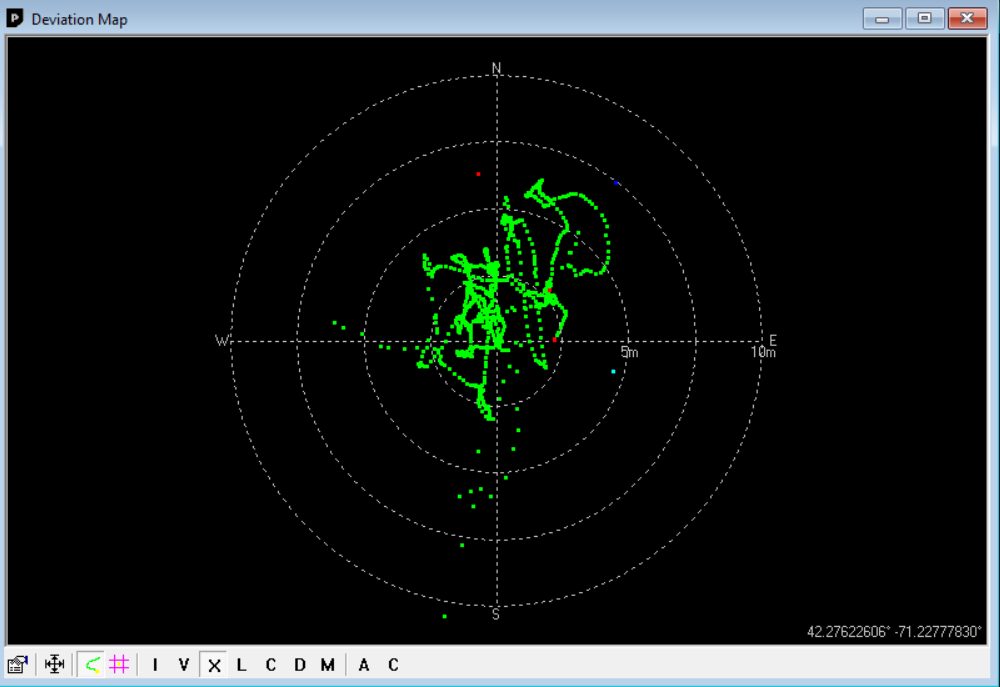

## Get the coordinates of a place

- On your computer, open [Google Maps](https://www.google.com/maps). Zoom to Olin Campus. 

- Right-click the place or area on the map, you want Longitude and Latitude of.

- Select the latitude and longitude, this will automatically copy the coordinates.

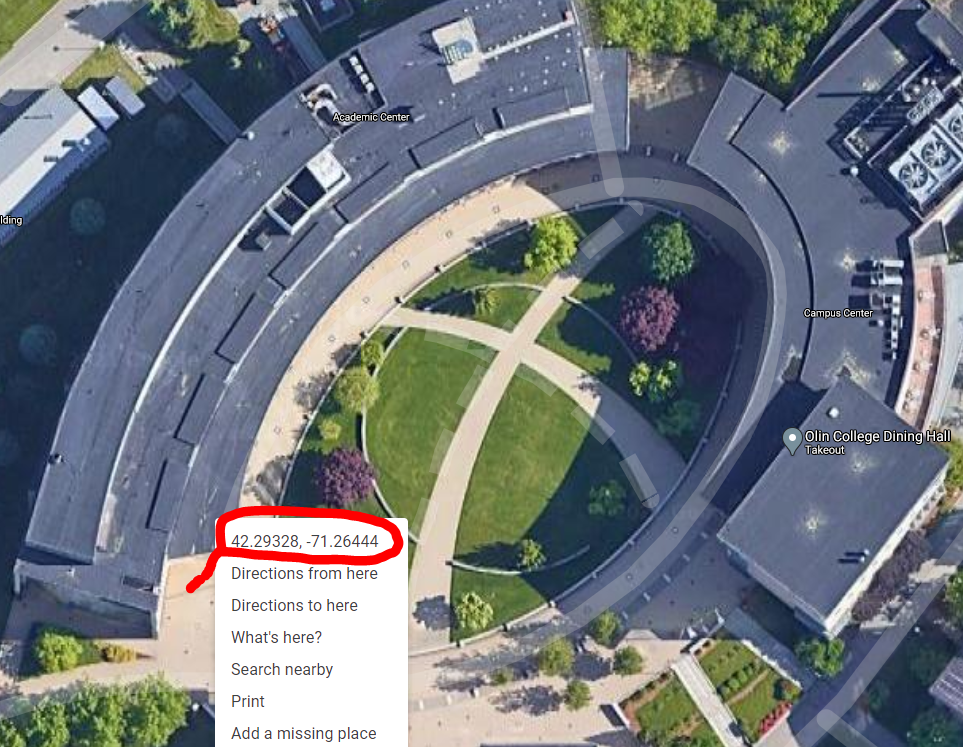

Click on a few waypoints and write down their coordinates for latter use.

Set up Ublox-Neo GPS

% neo = NEO_M8U(Pi);            % Create a GPS Class Instance
% pause(2);                          % Let GPS get up to speed
% 
% % the function neo.getBasic()
% % returns a struct with fields: longitude, lattitude, roll, pitch, and heading.
%        
% basic_data = neo.getBasic()
% 
% roverX = basic_data.longitude
% roverY = basic_data.lattitude
% roverHeading = basic_data.heading
% % Create a stand alone figure to plot GPS rover position data in
% gpsRoverPlot=figure('Name','Rover Position','NumberTitle','off','Visible','on');
% % Zoom down the plot to the Olin Oval coordinates in Latitude and Longitude
% geolimits([42.29246 42.29418],[-71.26537 -71.26258])
% % Plot out a trail line bewteen two waypoints just o demo line drawing
% geoplot([42.293 42.294],[-71.265 -71.262],'y-')
% hold on;
% % plot rover poition, you can cahnge this line to plot roverX and RoverY 
% geoplot(42.2935, -71.264, 'r*')
% % Import a satellite photo basemap to draw on
% geobasemap satellite
% legend('Rover GPS Track')
% movegui(gpsRoverPlot,'south');

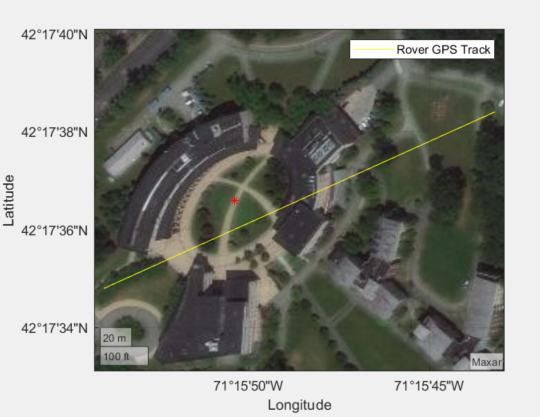

title('Planetary Rover Position')

Create a Mission Definition File (MDF) of Rover waypoints in a Matlab Table:

% create index fro MDF table
WayPoint = (1:1:11);                                        
WayPoint = WayPoint';

% create inital target waypoints
xLongitude = [ 42.276295 ; 42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295 ;42.276295;42.276295 ];
yLatitude = [ -71.227875 ; -71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875 ;-71.227875;-71.227875];

% build list of desired behaviors
% build Middion Definition File (MDF) table
Behavior = ['PauseDock______'; 'NavigationDock_'; 'FindDock_______'; 'Dock___________'; 
    'PauseNav_______'; 'NavPayload_____'; 'PayloadFindDock'; 'PayloadGoDock__'; 'PayloadDrop____';'PayloadFind____'; 'PayloadPickup__'];
MDF = table(WayPoint,xLongitude,yLatitude,Behavior)

MDF = 11×4 table
    WayPoint    xLongitude    yLatitude     Behavior  
    ________    __________    _________    ___________

        1         42.276       -71.228     [1×15 char]
        2         42.276       -71.228     [1×15 char]
        3         42.276       -71.228     [1×15 char]
        4         42.276       -71.228     [1×15 char]
        5         42.276       -71.228     [1×15 char]
        6         42.276       -71.228     [1×15 char]
        7         42.276       -71.228     [1×15 char]
        8         42.276       -71.228     [1×15 char]
        9         42.276       -71.228     [1×15 char]
       10         42.276       -71.228     [1×15 char]
       11         42.276       -71.228     [1×15 char]


Note: use curly braces { } to extract data from a table, in this case MDF

WPn = 1;
wayPointX = MDF{WPn,2}

wayPointX = 42.2763

wayPointY = MDF{WPn,3}

wayPointY = -71.2279

roverBehavior = MDF{WPn,4} 

roverBehavior = 'PauseDock______'


% movPlot=figure('Name','LocalSensorMap','NumberTitle','off','Visible','on');
% figure(movPlot)
% plotv([0;0],'-')
curvePlot=figure('Name','curvePlot','NumberTitle','off','Visible','on');


Create global variables  and an index for tracking the iterations.

sampleTime = 0.5;                                  % Sample time [s]
t = 0:sampleTime:100;                              % Time array
r = rateControl(1/sampleTime);                     % reset control loop  rate
reset(r);                                          % reset loop time to zero

Ready to run , ask operator if they are set and suggest they move plots to a visable position

userInput = questdlg('Ready to run Rover? Choose Mission', 'Mission Menu', 'Navigation', 'Payload', 'Cancel', 'extra')

**Run  control loop **( code that runs over and over )

if (strcmp(userInput,'Navigation'))
    controlFlag = 1;                     % create a loop control
    WPn = 2;                             % Set rover behaviour
else 
    if (strcmp(userInput,'Payload'))
    controlFlag = 1;                     % create a loop control
    WPn = 6;                             % Set rover behaviour
    end
end
if(strcmp(userInput,'Cancel'))
    controlFlag = -1;  
end
ACT_moveRover(roverServos, 0, -0.8)
pause(3.5)
ACT_moveRover(roverServos, -30, -0.7)
pause(2.4)

 steerAngle = 0; velocity = 0;
ACT_moveRover(roverServos,steerAngle,velocity);

while (controlFlag > 0)           % loop for number of elements in t
    
    ACT_moveRover(roverServos,steerAngle,velocity*0.25);
    controlTime = r.TotalElapsedTime;    % running register of control loop time
    
    % SENSE ------------------------------ called inside the THINK
    % functions
    
    
    % add a GPS read here ********************************
    
    %THINK------------------------------------------------------------
    % add code here that checks rovers curretn state with goal in MDF
    % and updates target waypoint appropriately
    roverBehavior = MDF{WPn,4}
    wayPointx = 0;
    wayPointY = 0;
    % compute what  should do next
    [steerAngle,velocity, WPn] = THINK(WPn, roverBehavior, roverCam, roverServos, adcDevice1, adcDevice2, piCamWindow, curvePlot);
%     figure(movPlot)
%     plotv([velocity*cos(steerAngle);velocity*sin(steerAngle)],'-')
    % ACT-------------------------------------------------------------
    % command both servo motors to desired velocity
%     PlotServoSettings(localServoPlot,comSteer, comSpeed); 
    ACT_moveRover(roverServos,steerAngle,velocity);
    %ACT_movePayload(roverServos, clawState);
    % replace above joystick code when you get your THINK code done
    % by swapping comSteer for steerSetPoint and 
    % comSpeed for driveSetPoint
   
    waitfor(r);                          % wait for loop cycle to complete  
    controlFlag = controlFlag+1;         % increment loop
    pause(4);
end 
% if (strcmp(userInput,'Yes'))

### Mission data processing

For many  applications, you will need to post-process the data collected after

the mission. 

  % Plot and store mission data vs. time, maybe yoru gps rover track?
  % write experimental data to a file for later use
%   save steerServoData.dat steerServoData -ascii  
%   save driveServoData.dat driveServoData -ascii  

### Clean shut down

finally, with most embeded  controllers, its good practice to put 

all actualtors into a safe position and then release all control objects and shut down all

communication paths. This keeps systems form jamming when you want to run again.

% Stop program and clean up the connection to Pi
% when no longer needed 
  pinSteer = 1;                                   % set Steer servo to pin 1
  pinSpeed = 3;                                   % set Speed servo to pin 3
  pinCamTilt = 4;                                 % set PiCam tilt servo to pin 4
  pinCamPan = 5;                                  % set PiCam pan servo to pin 5
  pinPayClose = 6;                                % set Payload Close servo to pin 6
  pinPayTilt = 7;                                 % set Payload tilt servo to pin 7
 
  comSteer = 50;                                % set intial steer command to 0 angle
  comSpeed = 50;                                  % set intial speed command to 0 speed
  comCamTilt = 0;                                 % set intial PiCam tilt command to 0 angle
  comCamPan = 0;                                  % set intial PiCam pan command to 0 angle
  comPayClose = 0;                                % set intial close command to 0 angle
  comPayTilt = 0;                                 % set intial tilt command to 0 angle
 
  roverServos.setServoPWM(pinSteer,comSteer);           % Set steering servo center position
  roverServos.setServoPWM(pinSpeed,comSpeed);           % Set Rover speed to zero
  roverServos.setServoPWM(pinCamTilt,comCamTilt);       % Set PiCam tilt servo to center position
  roverServos.setServoPWM(pinCamPan,comCamPan);         % Set PiCam pan servo to center position
  roverServos.setServoPWM(pinPayClose,comPayClose);     % Set Payload Claw to close position
  
  close all;                           % clear data figure plots
  clc                                  % clear commad window
  clear Pi                        % clear Pi object
  beep              % play system sound to let user know program is ended
  

Check quasi real-time loop performance (Dave and Matlab working on ways to speed this up)

  disp(r);
  stats = statistics(r)                % check real-time loop execution time stats
  disp('Rover Test program has ended');
  disp('Dont forget to shut down Pi cleanly before you power it off');

*At end of each programming session, please don't forget to shutdown your Pi cleanly by using the follwing at the command line:*

## `h = Pi`

## `h.execute('sudo shutdown -h now')`

  % leave next line commented out
  %  profile viewer                    % view code runtimes graphically

** Functions **(store this codes local functions here)

In practice for modularity, readability and longitevity, your main  code should be as brief as possible and the bulk of the work should be done by functions

For this Rover test LiveScript, many of the critical functions are embedded in class definitions in external files.

The functions are all in separate .m files in the 'functions/' folder for readability